% Define the data for lower limit, upper limit, and frequency
lowerLimits = [0,20,40,60,80,100,120,140,160,180,200,220]; 
upperLimits = [20,40,60,80,100,120,140,160,180,200,220,240]; 
frequencies = [8,12,14,63,31,85,14,75,14,47,23,14];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

         0            20            8    
        20            40           12    
        40            60           14    
        60            80           63    
        80           100           31    
       100           120           85    
       120           140           14    
       140           160           75    
       160           180           14    
       180           200           47    
       200           220           23    
       220           240           14    




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 125.30


fprintf('Median: %.2f\n', medianValue);

Median: 110.00


fprintf('Mode: %.2f\n', modeValue);

Mode: 110.00


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 53.34


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 79.40


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: 30.60


fprintf('Karl: %.2f\n', Karl);

Karl: 0.29


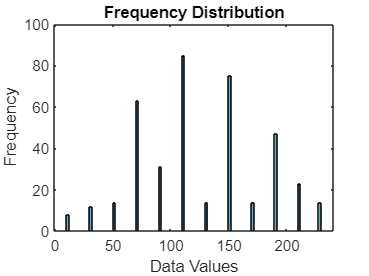


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');